clear;

cs = crystalSymmetry('cubic');
ss = specimenSymmetry('mmm');

b = Miller(1,-2,1,cs,'UVW');
n = Miller(1,1,1,cs,'HKL');
sSPartial = slipSystem(b,n);
sSFull = slipSystem.fcc(cs);
sS = [sSFull;sSPartial];
sSAll = sS.symmetrise;

Full slip means only full slip, similarily partial and twin means both ways partial and one way partial respectively

Full = 1:24; 
Partial = 25:48;
Twin = [25,26,27,31,32,34,37,38,40,43,44,46];
% sSAll.CRSS(1:24) =1e5; % This suppresses full slip
% sSAll.CRSS(Partial) =1e5; % This suppresses partial slip
sSAll.CRSS(Twin) =1e5; % This suppresses reverse partial slip and thus allows twinning

If you want to load data from a text file. If not on the path then addpath

load sol500.txt;
eul_ini = sol500*degree;

If you want to input a grid data from euler space

% phi1_id = 0;
% phi_id = 0;
% phi2_id = 0;
% range = 10;
% spacing = 2.5;
% eul_ini = grid2euler(phi1_id, phi_id, phi2_id,range,spacing);

If you want to just input an orientation defined by euler angles

% eul_ini = [5, 5 ,0]*degree;

ori0 = orientation('Euler',eul_ini,cs,ss);
ori = ori0;
plotPDF(ori0,Miller({1,1,1},cs),'contourf','complete')


q = 0; % Rolling velocity gradient
% epsilon = 1* tensor.diag([1 -q -(1-q)],'name','strain'); % Wrong syntax
epsilon = 3 * tensor(diag([1 -q -(1-q)]),'name','strain');
epsilon.CS = ss;

%
numIter = 15;
progress(0,numIter);

progress: 0%


progress: 7%


progress: 13%


progress: 20%


progress: 27%


progress: 33%


progress: 40%


progress: 47%


progress: 53%


progress: 60%


progress: 67%


progress: 73%


progress: 80%


progress: 87%


progress: 93%


progress: 100%


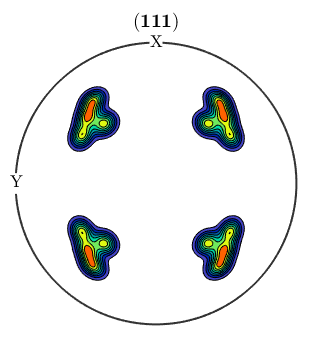

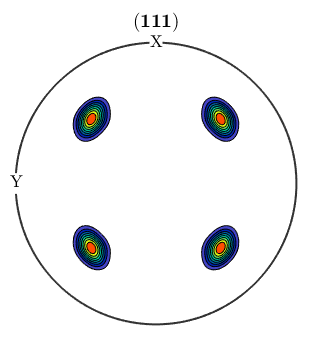

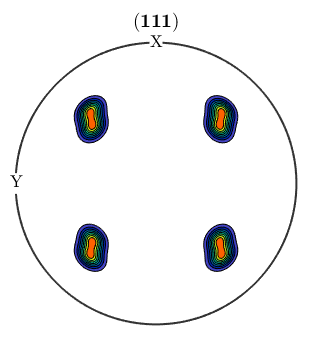

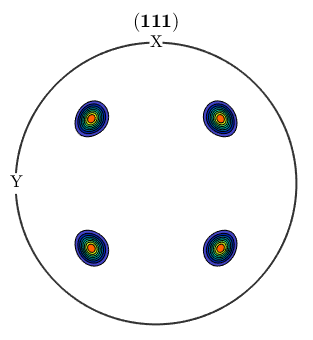

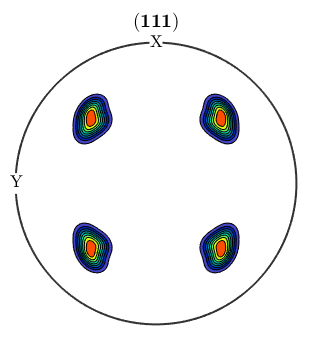

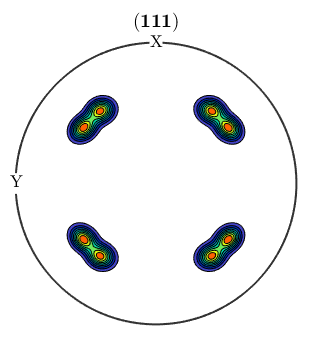

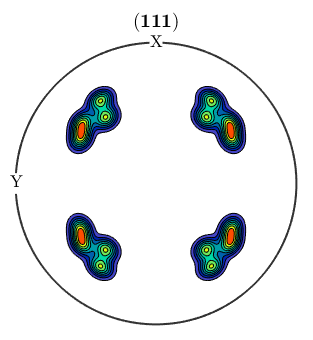

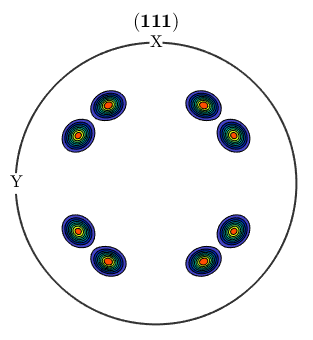


for sas=1:numIter

  % compute the Taylor factors and the orientation gradients
  [M,~,mori] = calcTaylor(inv(ori) * epsilon ./ numIter, sSAll,'silent');% [M,b,mori]

  % rotate the individual orientations
  ori = ori .* mori;
  progress(sas,numIter);
  figure
  plotPDF(ori,Miller({1,1,1},cs),'contourf','complete')
end

progress= 100;%


% plot the resulting pole figures
% figure
% plotPDF(ori,Miller({1,1,1},cs),'contourf','complete')
mtexColorbar